# Actividad 1.5 (Evaluación)

Ejercicio 1

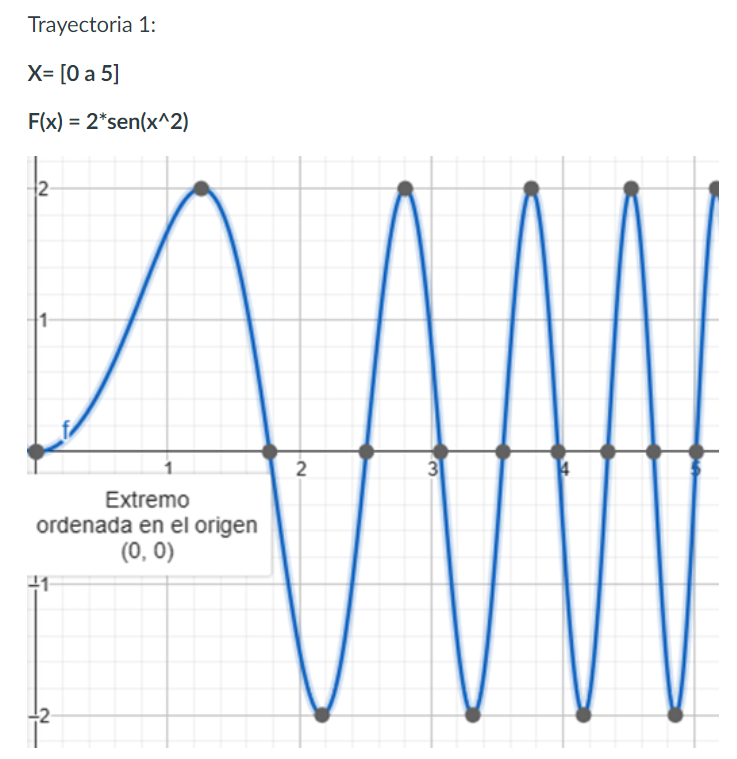

Para el primer ejercicio se utilizo la función que modela el sistema. primero se modifico el tiempo de simulacion de tal manera que los valores de x llegaran hasta 5, luego usando el vector de tiempo con un intervalo de 0.1 y la funcion de "2*sin(x^2)"se pudo parametrizar la función y obtener las coordenadas de la función a lo largo de la trayectoria y de esta manera simplemente tener una velocidad lineal que fuera a todos los puntos, dependiendo del tamaño del vector de tiempo, va a ser lo preciso de la trayectoria, es decir, entre más muestras más preciso, por ultimo se definieron las velocidades de referencia .... ya no me dio tiempo :(

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


ts = 0.1;            % Tiempo de muestreo en segundos (s)
velocidad_lineal = 1;
velocidad_angular = 1;

tf = 38;             % Tiempo de simulacion en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

f = 2*sin(t.^2);

coordenadas = [t',f'];

r = zeros(1,size(coordenadas, 1));
radLocal = zeros(1,size(coordenadas, 1));
radGlobal = zeros(1,size(coordenadas, 1));
side_length_local = zeros(1,size(coordenadas, 1));
side_length_global = zeros(1,size(coordenadas, 1));

for j = 1:size(coordenadas, 1)-1
    punto1 = coordenadas(j, :);
    punto2 = coordenadas(j+1, :);
    r(j) = sqrt((punto2(1)-punto1(1))^2 + (punto2(2)-punto1(2))^2);
    radLocal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
    side_length_local(j) = round(r(j)/ts/velocidad_lineal) + 1;
    if j==1
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j);
    else
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1))-radLocal(j-1); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j)+side_length_global(j-1);
    end
    
end


distancia_total = 0;
for j=1:size(coordenadas, 1)-1
    distancia_total = r(j) + distancia_total;
end

tiempo_recorrido = distancia_total/velocidad_lineal+((size(coordenadas, 1)-1)*ts);


%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%


%u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
%w = velocidad_angular*zeros(1, N); % Velocidad angular de referencia (rad/s)

u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
w = velocidad_angular*zeros(1, N); % Velocidad angular de referencia (rad/s)

inc = 1;
for i=1:N
    if i == 1
        w(i) = radGlobal(1)/ts;
        u(i) = 0;
    end
    if i == 1+side_length_global(inc)
        w(i) = (radGlobal(inc+1))/ts;
        u(i) = 0;
        
        inc = inc +1;
    end
    
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-1 6 -3 3 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');




Ejercicio 2

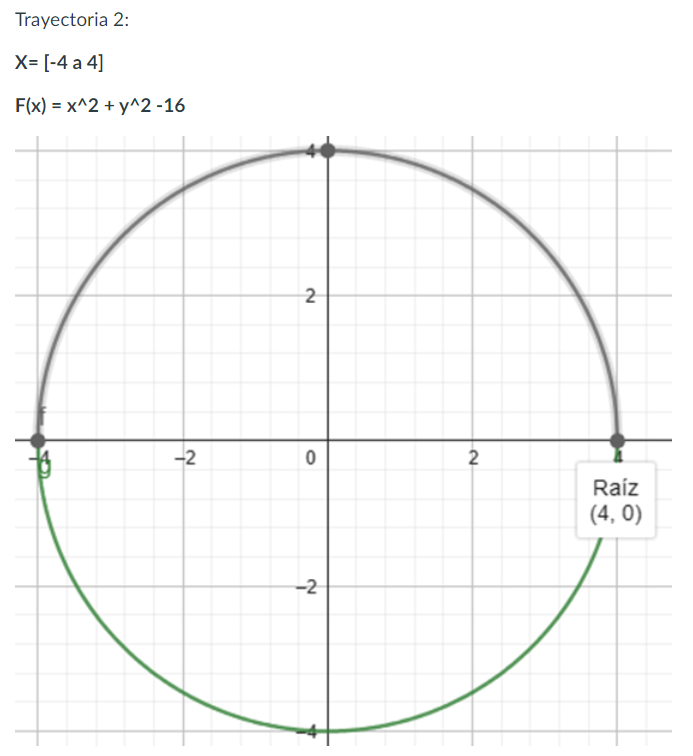

Para la segunda trayectoria primero se definio el tiempo como 2*pi para completar la circunferencia, pero falataba una muestra para completar el trazo, por lo que se agrego manuelmente en el tiempo quedando como 2*pi+0.1, de igual manera se modifico el marco inercial de (-5,-5) hasta (5,5), luego se modificaron las condiciones iniciales en (0,-4) para que se trazara el circulo de forma adecuada, pero hubo un retraso y empezaba en -0.2 en x, por lo que en condiciones adicionales se arreglo eso con un inicio en (0.2,-4). Por último para hacer el circulo, se utilizo la velocidad angular y lineal, poniendo la lineal 4 veces más que la angular, para poder obtener el circulo de diametro de 4.

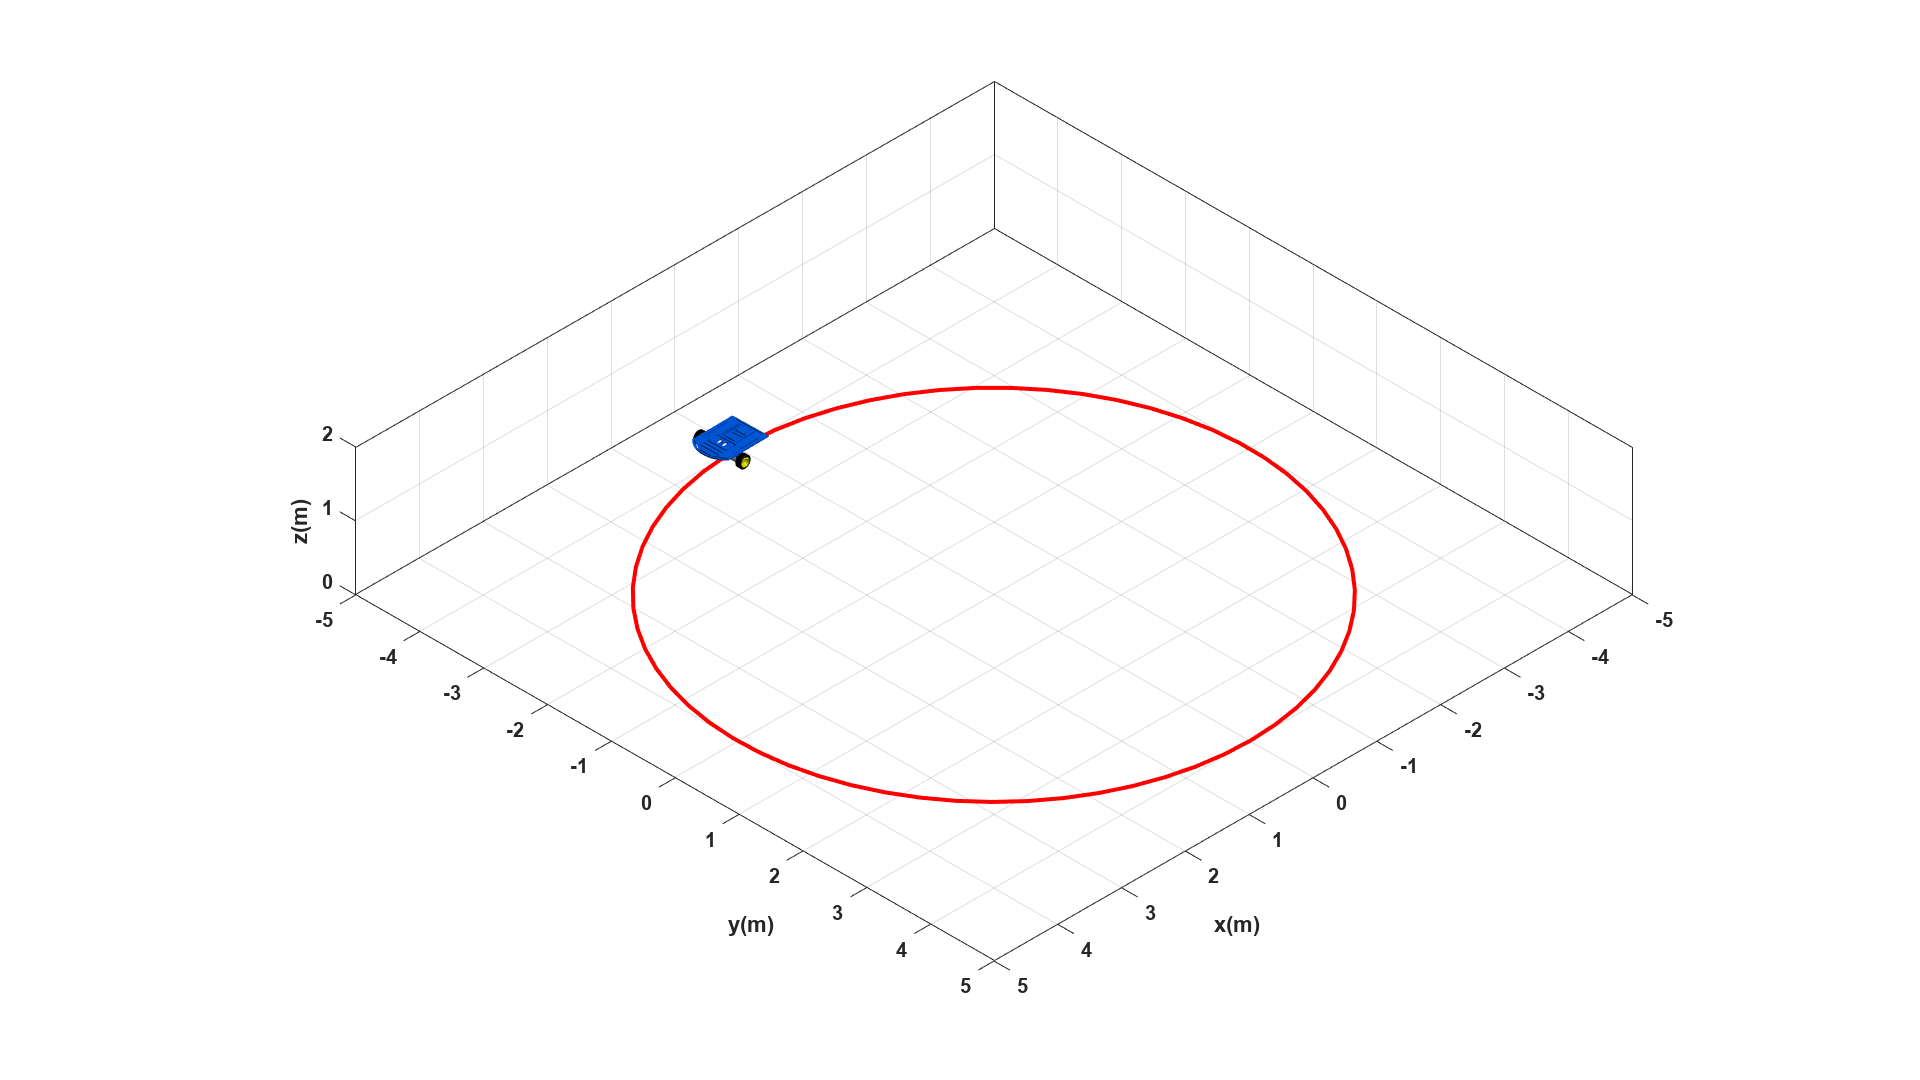

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

coordenadas = [0,0 ; -4,0 ; 0,-4 ; 4,0 ; 0,4 ; -4,0];

ts = 0.1;            % Tiempo de muestreo en segundos (s)
velocidad_lineal = 4;
velocidad_angular = 1;

r = zeros(1,size(coordenadas, 1));
radLocal = zeros(1,size(coordenadas, 1));
radGlobal = zeros(1,size(coordenadas, 1));
side_length_local = zeros(1,size(coordenadas, 1));
side_length_global = zeros(1,size(coordenadas, 1));

for j = 1:size(coordenadas, 1)-1
    punto1 = coordenadas(j, :);
    punto2 = coordenadas(j+1, :);
    r(j) = sqrt((punto2(1)-punto1(1))^2 + (punto2(2)-punto1(2))^2);
    radLocal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
    side_length_local(j) = round(r(j)/ts/velocidad_lineal) + 1;
    if j==1
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j);
    else
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1))-radLocal(j-1); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j)+side_length_global(j-1);
    end
    
end


distancia_total = 0;
for j=1:size(coordenadas, 1)-1
    distancia_total = r(j) + distancia_total;
end

tiempo_recorrido = distancia_total/velocidad_lineal+((size(coordenadas, 1)-1)*ts);

tf = 2*pi+0.1;             % Tiempo de simulacion en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0.2;    % Posicion inicial eje x
y1(1) = -4;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%


%u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
%w = velocidad_angular*zeros(1, N); % Velocidad angular de referencia (rad/s)

u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
w = velocidad_angular*ones(1, N); % Velocidad angular de referencia (rad/s)



%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-5 5 -5 5 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

Ejercicio 3

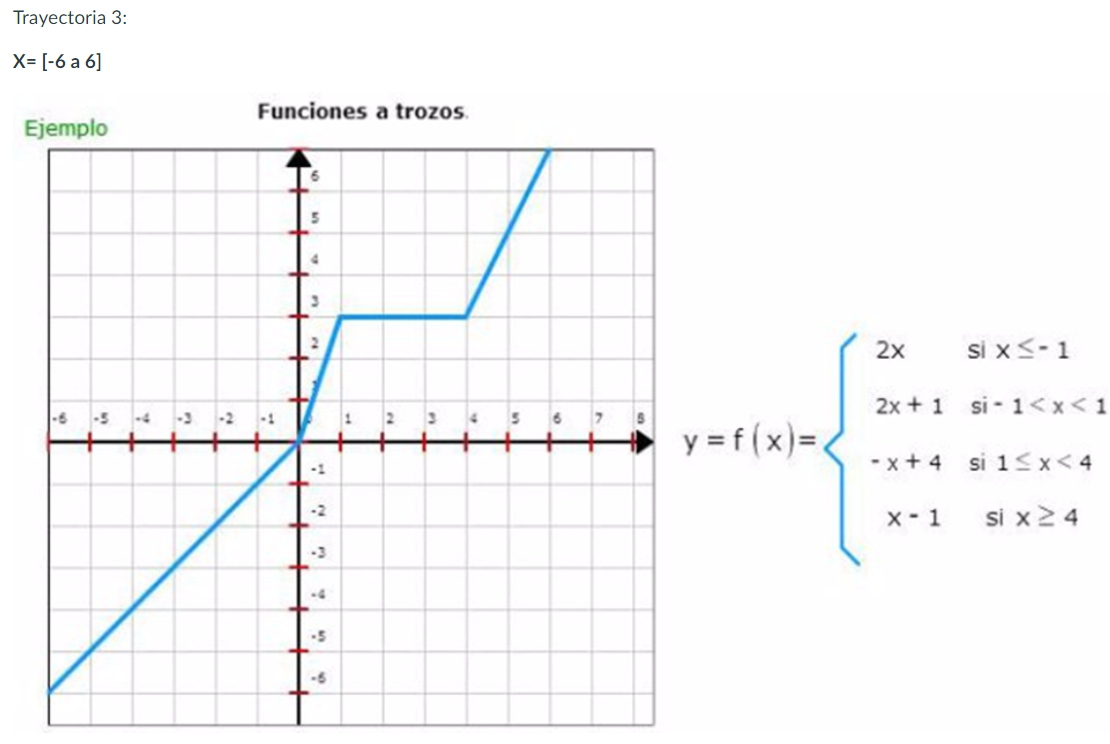

Para el trazo de la tercera trayectoria se utilizaron las coordenadas de cada punto donde hace giros y solo se uso la velocidad lineal, la angular se mantuvo en 0 debido a que no hay curvas y solo se usa la velocidad lineal. Después se definieron los valores iniciales, donde claramente se ve en la imagen que el trazo inicia en (-6,-6), además de ajustar el marco de referencia desde (-6,-6) hasta (6,6) para visualizar todo el tiempo el robot. Luego se definieron las velocidades de referencia, donde por medio de un for de 1 hasta N (muestras) y con ayuda de las coordenadas, el robot fue recorriendo cada punto y haciendo los giros correspondientes para la siguiente coordenada. 

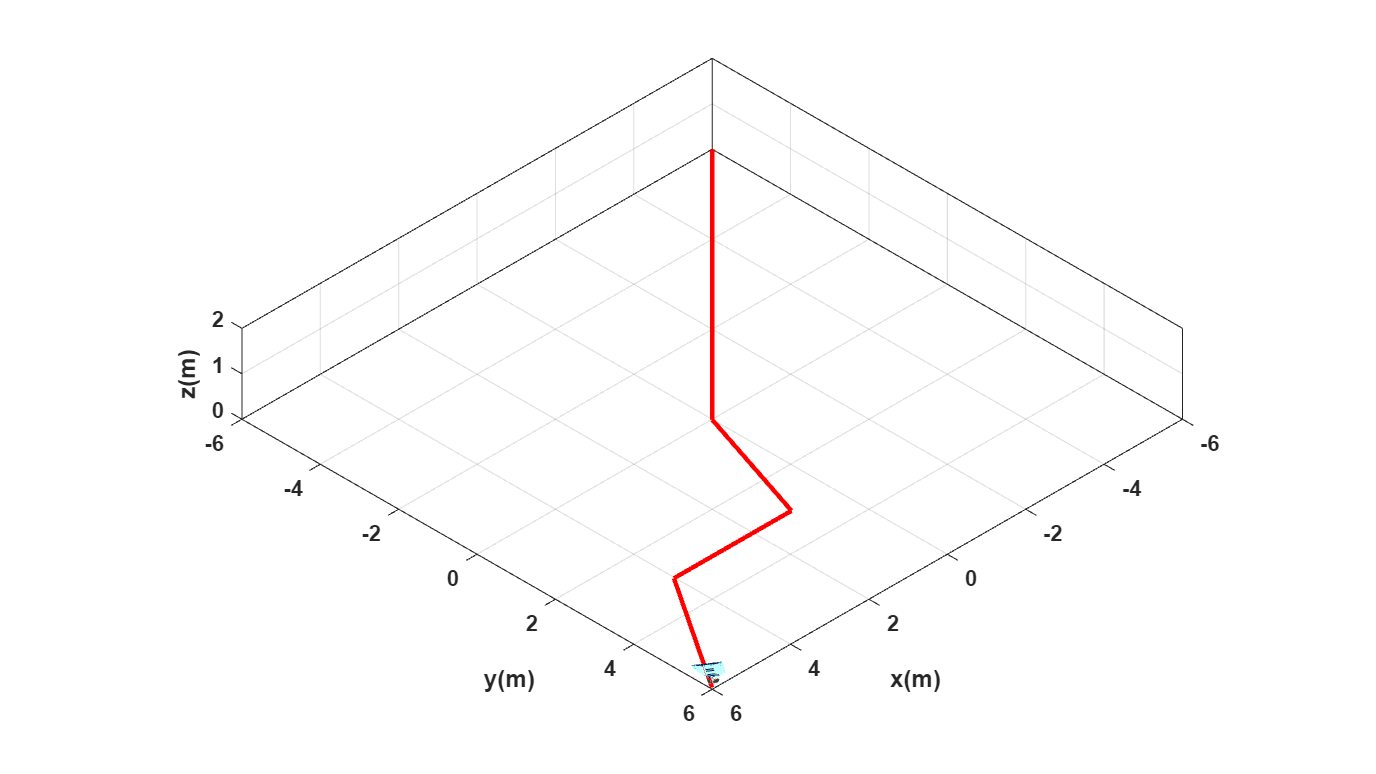

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

coordenadas = [-6,-6 ; 0,0 ; 1,3 ; 4,3 ; 6,6];

ts = 0.1;            % Tiempo de muestreo en segundos (s)
velocidad_lineal = 1;


r = zeros(1,size(coordenadas, 1));
radLocal = zeros(1,size(coordenadas, 1));
radGlobal = zeros(1,size(coordenadas, 1));
side_length_local = zeros(1,size(coordenadas, 1));
side_length_global = zeros(1,size(coordenadas, 1));

for j = 1:size(coordenadas, 1)-1
    punto1 = coordenadas(j, :);
    punto2 = coordenadas(j+1, :);
    r(j) = sqrt((punto2(1)-punto1(1))^2 + (punto2(2)-punto1(2))^2);
    radLocal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
    side_length_local(j) = round(r(j)/ts/velocidad_lineal) + 1;
    if j==1
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j);
    else
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1))-radLocal(j-1); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j)+side_length_global(j-1);
    end
    
end


distancia_total = 0;
for j=1:size(coordenadas, 1)-1
    distancia_total = r(j) + distancia_total;
end

tiempo_recorrido = distancia_total/velocidad_lineal+((size(coordenadas, 1)-1)*ts);

tf = tiempo_recorrido;             % Tiempo de simulacion en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -6;    % Posicion inicial eje x
y1(1) = -6;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%


%u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
%w = velocidad_angular*zeros(1, N); % Velocidad angular de referencia (rad/s)

u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
w = zeros(1, N); % Velocidad angular de referencia (rad/s)

for i=1:N
    if i == 1
        w(i) = radGlobal(1)/ts;
        u(i) = 0;
    end
    if i == 1+side_length_global(1)
        w(i) = (radGlobal(2))/ts;
        u(i) = 0;

    end
    if i == 1+side_length_global(2)
        w(i) = radGlobal(3)/ts;
        u(i) = 0;
    end
    if i == 1+side_length_global(3)
        w(i) = radGlobal(4)/ts;
        u(i) = 0;
    end
    
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-6 6 -6 6 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

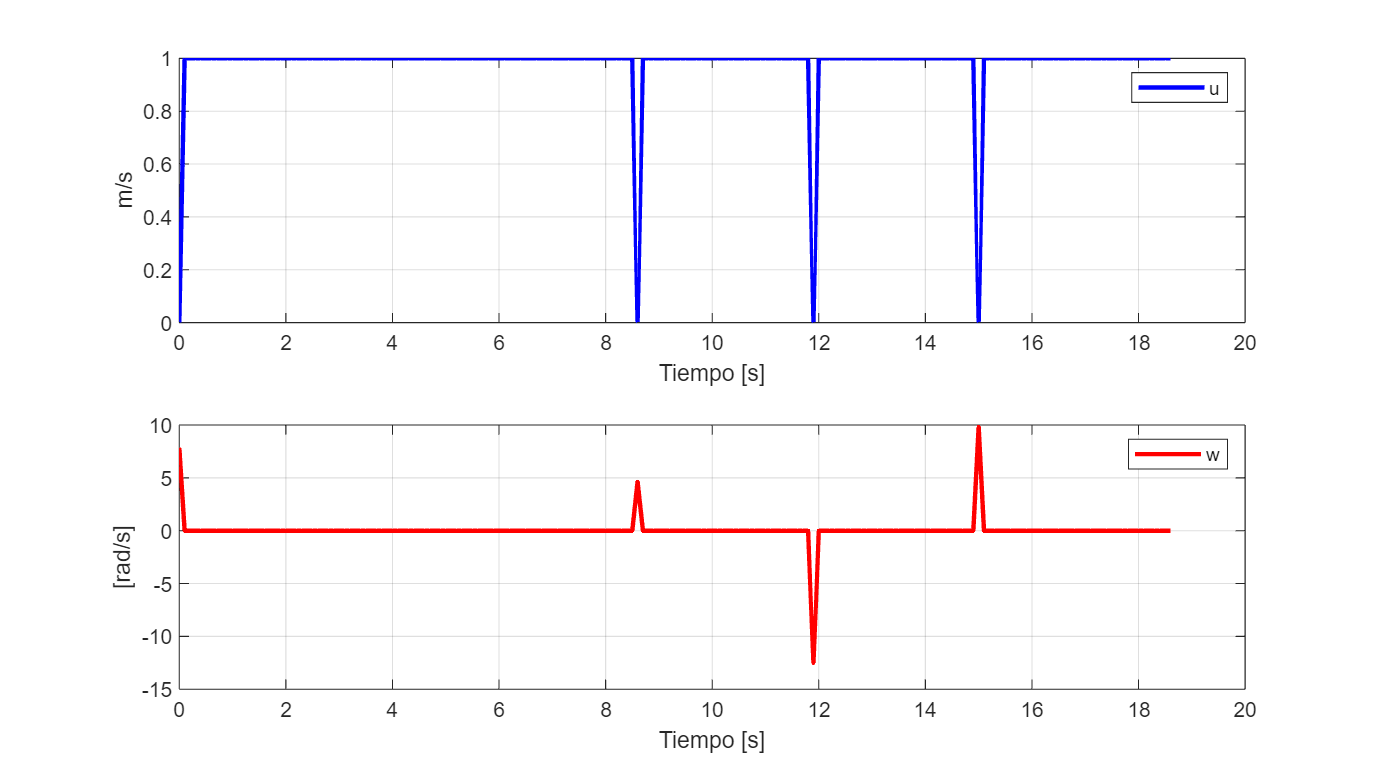


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');